clear;
clc;
mpc = case33open_new;
V_base = 10;	

P=mpc.bus(:,3);
N=size(P,1);
% path-branch incidence matrix
branch_info=mpc.branch(:,1:2);
P_bus=P(2:N,:);

[H] = gen_path_branch(branch_info,N);
H_modified=H(:,2:N);

Loss Factor Generation

R_branch=diag(mpc.branch(:,3));
p=2.*H_modified'*R_branch*H_modified*P_bus./V_base.^2;

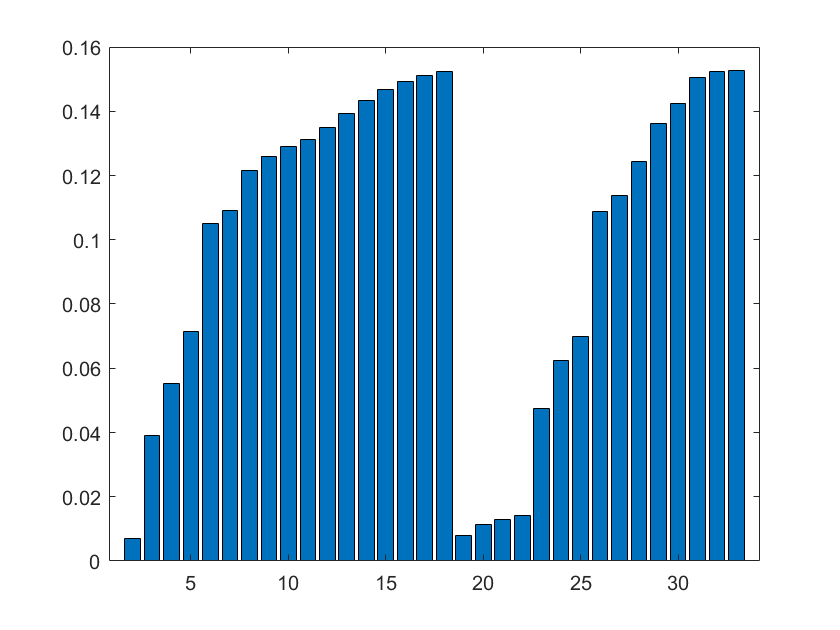

x=2:N;
bar(x,p)

**Other Means: Without Distributed Generator**

gen_num=size(mpc.gen,1);
del_DG=2:gen_num;
mpc.gen(del_DG,:)=[];

BPF_SOCP = OPF_SOCP_new(mpc);

SOCP optimization terminated.



mpopt = mpoption('out.all', 1);

casename = 'case33wdet_new';
my_mpc = loadcase(casename);
results_ac = runopf(my_mpc, mpopt);


MATPOWER Version 7.1, 08-Oct-2020 -- AC Optimal Power Flow
  AC OPF formulation: polar voltages, power balance eqns
MATPOWER Interior Point Solver -- MIPS, Version 1.4, 08-Oct-2020
 (using built-in linear solver)
Converged!

Converged in 1.65 seconds
Objective Function Value = 79.56 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses             33     Total Gen Capacity      20.0          -8.0 to 8.0
Generators         1     On-line Capacity        20.0          -8.0 to 8.0
Committed Gens     1     Generation (actual)      4.0               2.5
Loads             32     Load                     3.7               2.3
  Fixed           

results_dc = rundcopf(my_mpc, mpopt);


MATPOWER Version 7.1, 08-Oct-2020 -- DC Optimal Power Flow
MOSEK Version 9.2.40 -- default LP solver

MOSEK Version 9.2.40 (Build date: 2021-3-10 14:33:40)
Copyright (c) MOSEK ApS, Denmark. WWW: mosek.com
Platform: Windows/64-X86

The solution is optimal.

Converged in 0.26 seconds
Objective Function Value = 74.30 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses             33     Total Gen Capacity      20.0           0.0 to 0.0
Generators         1     On-line Capacity        20.0           0.0 to 0.0
Committed Gens     1     Generation (actual)      3.7               0.0
Loads             32     Load                     3.7     

lambda_base=mpc.gen(1,6);
LMP_simplified=(1+[0;p])*lambda_base;

% figure
% plot(results_ac.bus(:, 14), 'x', 'LineWidth', 1, 'markersize', 8);
% % hold on
% % plot(1:N, BPF_SOCP.LMP, 'r:^', 'markersize', 8);
% hold on
% plot(1:N,LMP_simplified,'^', 'markersize', 8)
% 
% legend('LMP-AC','LMP-Simplifications');
% xlabel('Bus Number '); ylabel('LMP ($/MWh)'); grid on;

**With DG**

G_loc=[25,28,31];
G_power=[0.66,0.6,0.67];
P_copy =P;
for i=1:size(G_loc,2)
    loc=G_loc(i);
    power=G_power(i);
   P_copy(loc)= P_copy(loc)-power;
end
P_bus_new=P_copy(2:N,:);
LFP_new=2.*H_modified'*R_branch*H_modified*P_bus_new./V_base.^2;
for i=1:size(G_loc,2)
    loc=G_loc(i)-1;
    disp(LFP_new(loc))
end

    0.0177

    0.0328

    0.0285



disp(LFP_new(1))

    0.0033



LMP_3=(1+[0;LFP_new])*lambda_base;

mpc2 = case33open_new_DG;
BPF_SOCP2 = OPF_SOCP_new(mpc2);

SOCP optimization terminated.


mpopt2 = mpoption('out.all', 1);
results_ac2 = runopf('case33wdet_new_DG', mpopt2);


MATPOWER Version 7.1, 08-Oct-2020 -- AC Optimal Power Flow
  AC OPF formulation: polar voltages, power balance eqns
MATPOWER Interior Point Solver -- MIPS, Version 1.4, 08-Oct-2020
 (using built-in linear solver)
Converged!

Converged in 0.25 seconds
Objective Function Value = 38.12 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses             33     Total Gen Capacity      21.9          -8.0 to 8.0
Generators         4     On-line Capacity        21.9          -8.0 to 8.0
Committed Gens     4     Generation (actual)      3.8               2.4
Loads             32     Load                     3.7               2.3
  Fixed           

% figure
% plot(results_ac2.bus(:, 14), 'x', 'LineWidth', 1, 'markersize', 8);
% hold on
% plot(1:N, BPF_SOCP2.LMP, 'r:^', 'markersize', 8);
% hold on
% plot(1:N,LMP_3,'^', 'markersize', 8)
% 
% legend('LMP-AC','LMP-SOCP','LMP-Simplifications');
% xlabel('Bus Number '); ylabel('LMP ($/MWh)'); grid on;

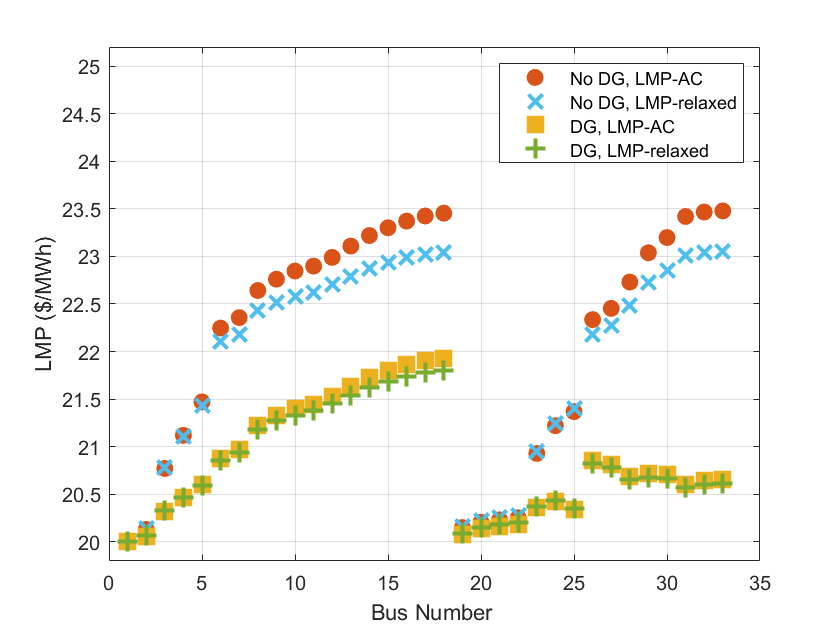


figure
plot(1:N,results_ac.bus(:, 14),'o', 'markersize', 8,'MarkerEdgeColor',[0.8500, 0.3250, 0.0980],'MarkerFaceColor',[0.8500, 0.3250, 0.0980])
ylim([19.8,25.2])
% hold on
% plot(1:N, BPF_SOCP.LMP, 'r:^', 'markersize', 8);
hold on
plot(1:N,LMP_simplified, 'x', 'LineWidth', 1, 'markersize', 10,'MarkerEdgeColor',[0.3010, 0.7450, 0.9330],'LineWidth',2)
hold on
plot(results_ac2.bus(:, 14), 's', 'LineWidth', 1, 'markersize', 10,'MarkerEdgeColor',[0.9290, 0.6940, 0.1250],'MarkerFaceColor',[0.9290, 0.6940, 0.1250]);
% hold on
% plot(1:N, BPF_SOCP.LMP, 'r:^', 'markersize', 8);
hold on
plot(1:N,LMP_3,'+', 'markersize', 10,'MarkerEdgeColor',[0.4660, 0.6740, 0.1880],'LineWidth',2)

legend('No DG, LMP-AC','No DG, LMP-relaxed', 'DG, LMP-AC','DG, LMP-relaxed');
xlabel('Bus Number '); ylabel('LMP ($/MWh)'); 
grid on;

**Theta**

max_theta=max(abs(results_ac.bus(:,9)))

max_theta = 1.1032

max_theta_DG=max(abs(results_ac2.bus(:,9)))

max_theta_DG = 2.7661

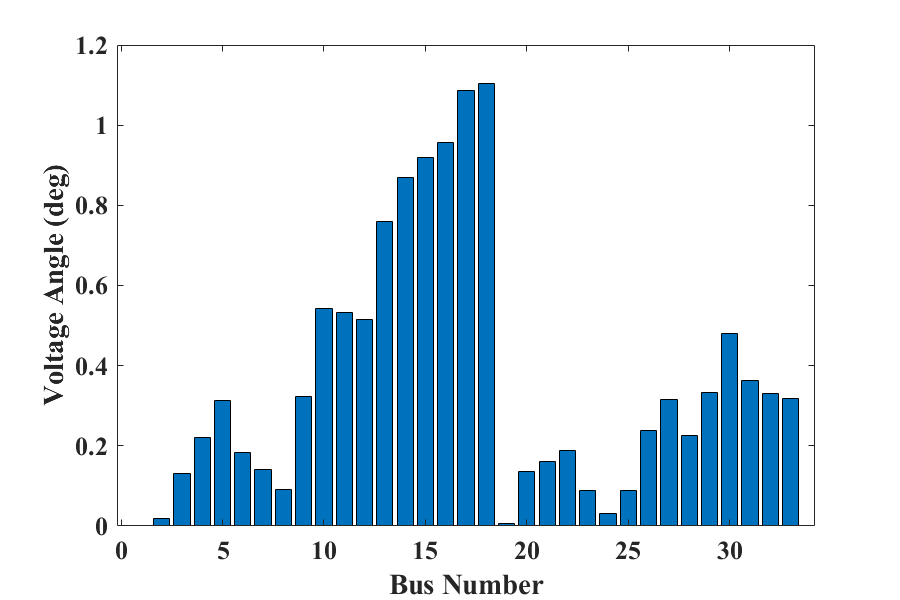

figure
bar(abs(results_ac.bus(:,9)))
xlabel('Bus Number' ,'FontSize',13.2,'FontName','Times New Roman','FontWeight','Bold')
ylabel('Voltage Angle (deg)' ,'FontSize',13.2,'FontName','Times New Roman','FontWeight','Bold')
set(gcf,'Position',[100 100 600 400]);
set(gca,'FontSize',13,'FontName','Times New Roman','FontWeight','Bold')

**Fact 1: Bus 9**

P_9=0.02:0.002:0.08;
All_LMP_9=zeros(1, size(P_9,2));
General_LMP_9=zeros(1, size(P_9,2));
All_LMP_18=zeros(1, size(P_9,2));
General_LMP_18=zeros(1, size(P_9,2));
for i=1:size(P_9,2)
    P_bus(9)=P_9(i);
    p=2.*H_modified'*R_branch*H_modified*P_bus./V_base.^2;
    temp_LMP=(1+[0;p])*lambda_base;
    All_LMP_9(1,i)=temp_LMP(9);
    All_LMP_18(1,i)=temp_LMP(18);
    
    my_mpc.bus(9,3)=P_9(i);
    results_ac = runopf(my_mpc, mpopt);
    General_LMP_9(1,i)=results_ac.bus(9, 14);
    General_LMP_18(1,i)=results_ac.bus(18, 14);
end


MATPOWER Version 7.1, 08-Oct-2020 -- AC Optimal Power Flow
  AC OPF formulation: polar voltages, power balance eqns
MATPOWER Interior Point Solver -- MIPS, Version 1.4, 08-Oct-2020
 (using built-in linear solver)
Converged!

Converged in 0.20 seconds
Objective Function Value = 78.65 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses             33     Total Gen Capacity      20.0          -8.0 to 8.0
Generators         1     On-line Capacity        20.0          -8.0 to 8.0
Committed Gens     1     Generation (actual)      3.9               2.5
Loads             32     Load                     3.7               2.3
  Fixed           

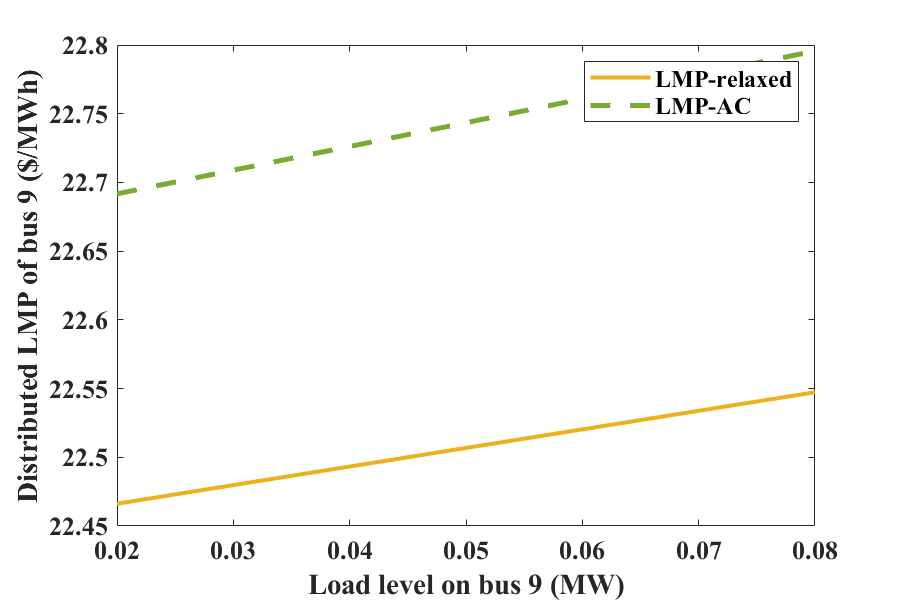

figure
plot(P_9,All_LMP_9,'LineWidth',2,'Color',[0.9290, 0.6940, 0.1250])
hold on
plot(P_9, General_LMP_9,'--','LineWidth',2.5,'Color',[0.4660, 0.6740, 0.1880])
legend('LMP-relaxed', 'LMP-AC' ,'FontSize',12,'FontName','Times New Roman','FontWeight','Bold')
xlabel('Load level on bus 9 (MW)' ,'FontSize',13.2,'FontName','Times New Roman','FontWeight','Bold')
ylabel('Distributed LMP of bus 9 ($/MWh)' ,'FontSize',13.2,'FontName','Times New Roman','FontWeight','Bold')
set(gcf,'Position',[100 100 600 400]);
set(gca,'FontSize',13,'FontName','Times New Roman','FontWeight','Bold')

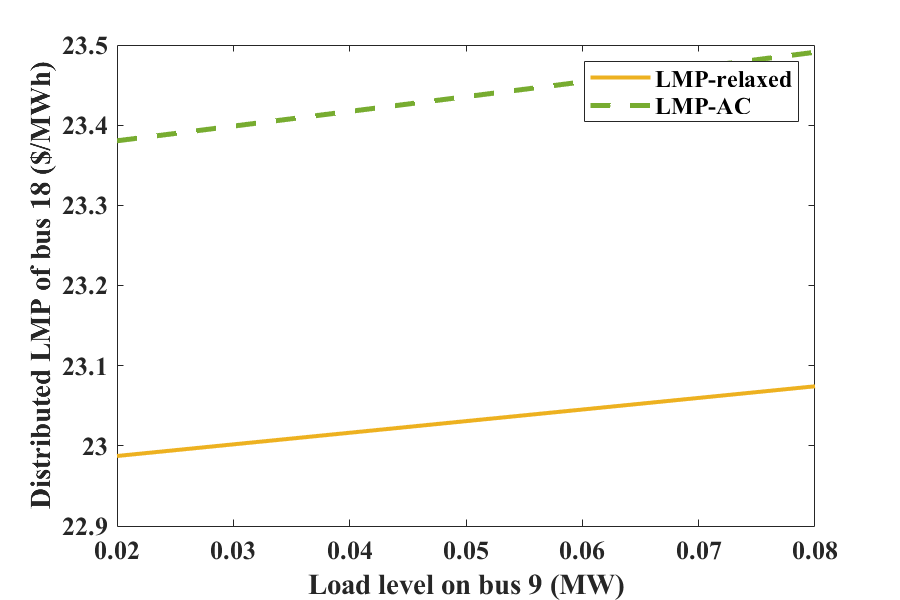

figure
plot(P_9,All_LMP_18,'LineWidth',2,'Color',[0.9290, 0.6940, 0.1250])
hold on
plot(P_9, General_LMP_18,'--','LineWidth',2.5,'Color',[0.4660, 0.6740, 0.1880])
legend('LMP-relaxed', 'LMP-AC' ,'FontSize',12,'FontName','Times New Roman','FontWeight','Bold')
xlabel('Load level on bus 9 (MW)' ,'FontSize',13.2,'FontName','Times New Roman','FontWeight','Bold')
ylabel('Distributed LMP of bus 18 ($/MWh)' ,'FontSize',13.2,'FontName','Times New Roman','FontWeight','Bold')
set(gcf,'Position',[100 100 600 400]);
set(gca,'FontSize',13,'FontName','Times New Roman','FontWeight','Bold')